% p3.m - band-limited interpolation

h = 1;
xmax = 10; 
clf
x = -xmax:h:xmax                               %computeional grid

x =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


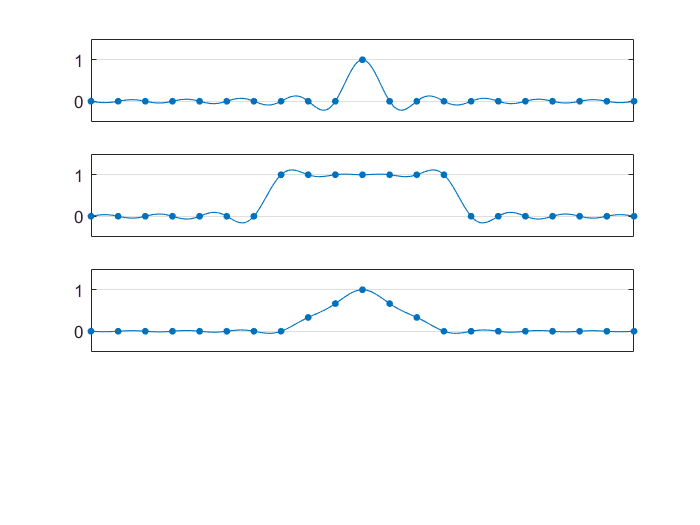

v =          0         0         0         0         0         0         0         0    0.3333    0.6667    1.0000    0.6667    0.3333         0         0         0         0         0         0         0         0


xx = -xmax - h / 20 : h / 10 : xmax + h / 20;  %poltting grid
for plt = 1:3
    subplot(4, 1, plt)
    switch plt
        case 1, v = (x == 0);                 % delta function
        case 2, v = (abs(x) <= 3);            % square wave
        case 3, v = max(0, 1 - abs(x) / 3)    % hat function
    end
    plot(x, v, '.', 'markersize', 14),
    grid on;
    p = zeros(size(xx));
    for i = 1:length(x)
        p = p + v(i) * sin(pi * (xx - x(i)) / h) ./ (pi * (xx - x(i)) / h);
    end
    line(xx, p, 'linewidth', .7),
    axis([-xmax xmax -0.5 1.5])
    set(gca, 'xtick', []),
    set(gca, 'ytick', [0 1])
end